# Getting Started with Procrustes cross-validation toolbox

## Description

Procrustes cross-validation is a new approach for validation of chemometric models. It makes possible to generate a new dataset, named *PV-set*, and use it for validation of models in the same way as with an independent validation set.

The current version of this toolbox contains methods for generating PV-set to validate Principal Component Analysis and SIMCA models (*pcvpca*), Principal Component Regression models (*pcvpcr*), and Partial Least Squares Regression models (*pcvpls*).

More details as well as implementation of the approach in other languages can be found in the project's GitHub repository ([https://github.com/svkucheryavski/pcv](https://github.com/svkucheryavski/pcv)). Theory and examples are described in the following publication (currently under peer-review):

S. Kucheryavskiy, O. Rodionova, A. Pomerantsev. *Procrustes cross-validation of multivariate regression models*. Submitted 2022.

## Examples

The examples replicate some of the results shown in the paper. 

The code of the examples is based on *Corn *dataset, which was downloaded from Eigenvector Research, Inc. website ([https://eigenvector.com/resources/data-sets/](https://eigenvector.com/resources/data-sets/)), where it is availble publicly. This dataset contains several NIR spectra of corn samples recorded using different instruments. For our examples we took "mp5" spectra and corrected them using Standard Normal Variate transformation. File "corn.mat" contains the corrected spectra as variable "X" and the moisture of the corns as variable "Y". 

The data file with both variables is a part of this toolbox, so you can load the data directly as it is shown in the code below:

% load preprocessed spectra (X) and moisture (Y) from the data file
load("corn.mat");

### Examples for PCA based models

Now let's generate the PV-set using PCA based generator. In this case we use 20 principal components and cross-validation based on Venetian blinds split with 4 segments. 

% define maximum number of PCs
A = 20; 

% create pseudo-validation set
Xpv = pcvpca(X, A, true, false, {"ven", 4});

The syntax of the method is as follows:

% pcvpca(X, nComp, Center, Scale, CV) 

Here *X* is the data matrix, *nComp* is number of components to use in PCA model, *Center* and *Scale* are logical parameters defining if data must be centered and/or standardized before PCA and *CV* is a parameter, which specifies cross-validation splits. See help text for the method for more details.

Now we can compare the original data and the PV-set visually:

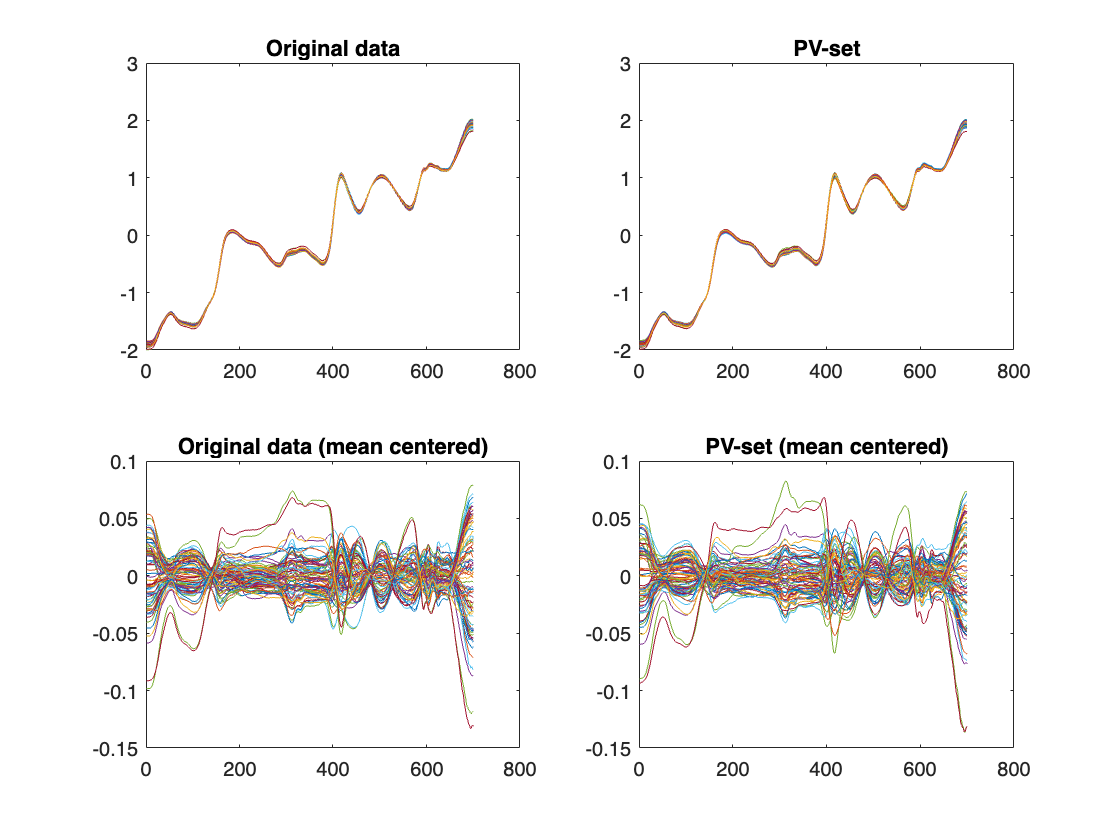

% show plot with original and generated spectra
figure
subplot 221
plot(X')
title("Original data")

subplot 222
plot(Xpv')
title("PV-set")

subplot 223
plot((X - mean(X, 1))')
title("Original data (mean centered)")

subplot 224
plot((Xpv - mean(Xpv, 1))')
title("PV-set (mean centered)")

As you can see the PV-set looks similar to the calibration set, but they are not identical. The next code creates PCA model using the original data, and then applies this model to the PV-set. After that, orthoginal and score distances are computed and shown as distance plot for A = 2 and A = 20. The code uses function *plotdistances()* which you will find at the end of this document.

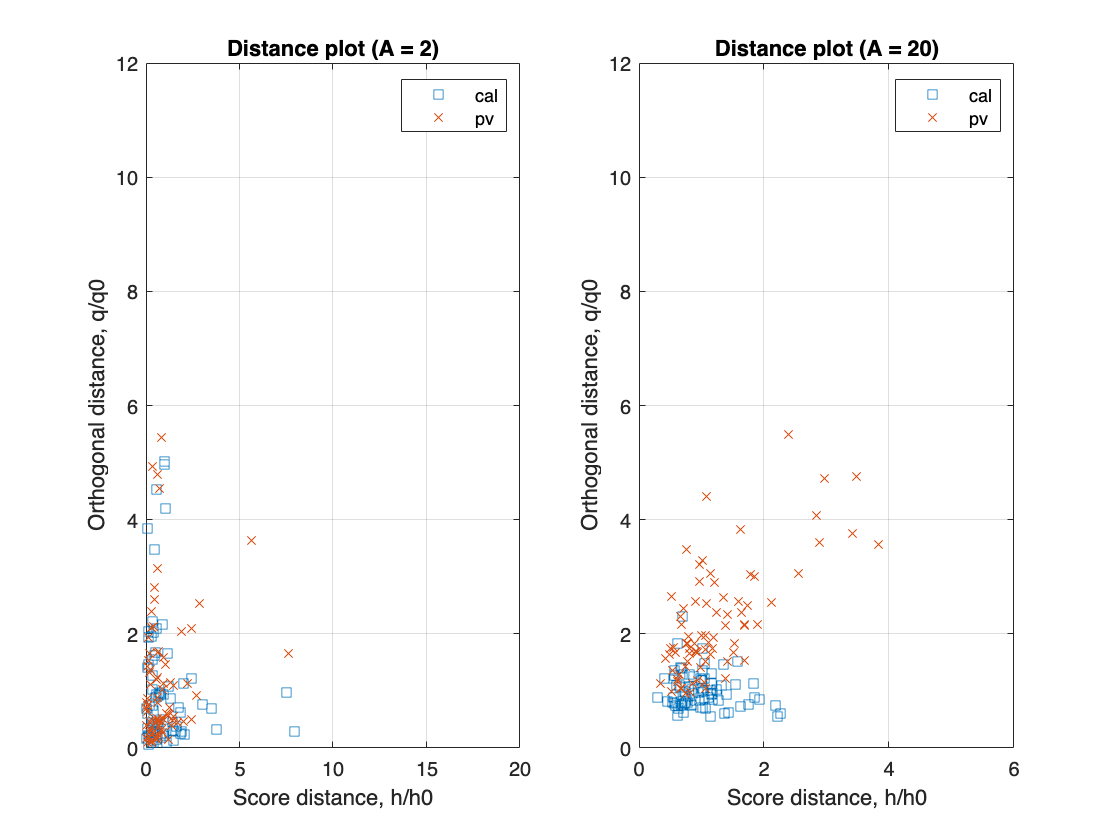

% mean center calibration and PV sets
mX = mean(X);
Xmc = X - mX;
Xpvmc = Xpv - mX;

% get PCA loadings for the calibration set
[~, ~, P] = svd(Xmc);
P = P(:, 1:A);

% compute eigenvalues - we need them for score distances
T = Xmc * P;
lambda = sum(T.^2) / (size(X, 1) - 1);

% create distance plot for A = 2 and A = 20 similar to shown in the paper
% but only for the new method
figure
subplot 121
plotdistances(P, lambda, Xmc, Xpvmc, 2)
xlim([0, 20])
ylim([0, 12])
subplot 122
plotdistances(P, lambda, Xmc, Xpvmc, 20)
xlim([0,  6])
ylim([0, 12])

As you can notice, PV-set shows a clear overfitting pattern in case of A = 20.

### Examples for PCR based models

The code below shows how to  generate the PV-set using PCR based generator. We use the same parameters as in PCA case but now we also provide the response values, Y. 

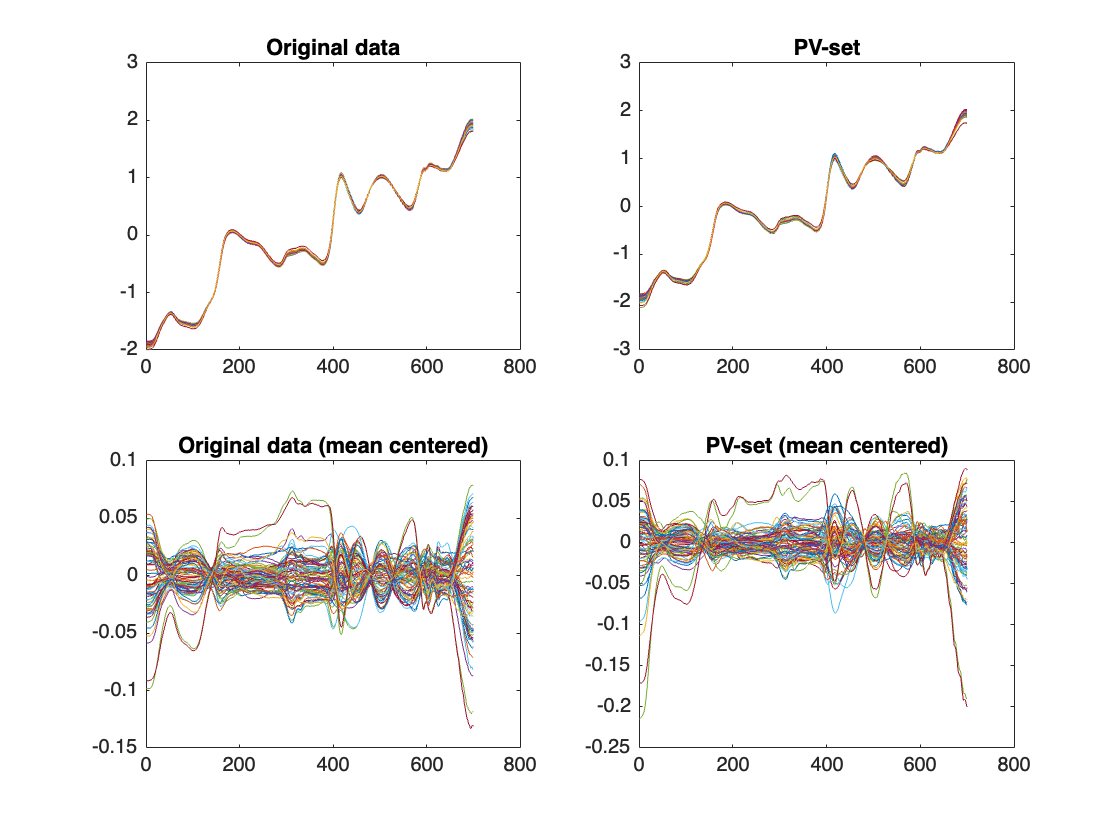

% create PV-set for PCR
Xpv = pcvpcr(X, Y, A, true, false, {"ven", 4});

% show plot with original and generated spectra
figure
subplot 221
plot(X')
title("Original data")

subplot 222
plot(Xpv')
title("PV-set")

subplot 223
plot((X - mean(X, 1))')
title("Original data (mean centered)")

subplot 224
plot((Xpv - mean(Xpv, 1))')
title("PV-set (mean centered)")

### Examples for PLS based models

The code below shows how to generate the PV-set using PLS based generator. This time we get both the PV-set and the matrix with scaling coefficients, D, (see the paper for details).

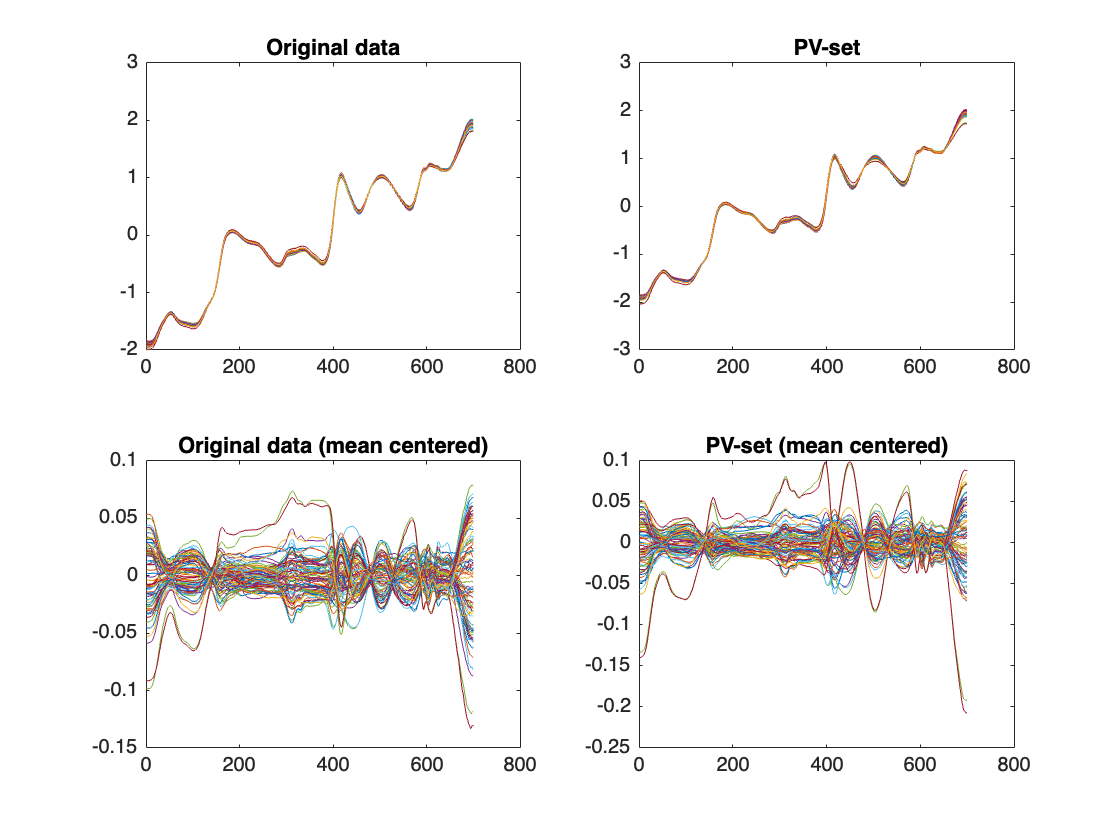

% create PV-set and also get matrix with scaling coefficients c.k/c (D)
[Xpv, D] = pcvpls(X, Y, A, true, false, {"ven", 4});

% show plot with original and generated spectra
figure
subplot 221
plot(X')
title("Original data")

subplot 222
plot(Xpv')
title("PV-set")

subplot 223
plot((X - mean(X, 1))')
title("Original data (mean centered)")

subplot 224
plot((Xpv - mean(Xpv, 1))')
title("PV-set (mean centered)")

Now let's create a PLS model and validate it using the created PV-set. The method *simpls *show in the block of code below is a SIMPLS algorithm for PLS regression, which is also a part of this toolbox. It resturns matrices with weights (R), X-loadings (P) and Y-loadings (C).

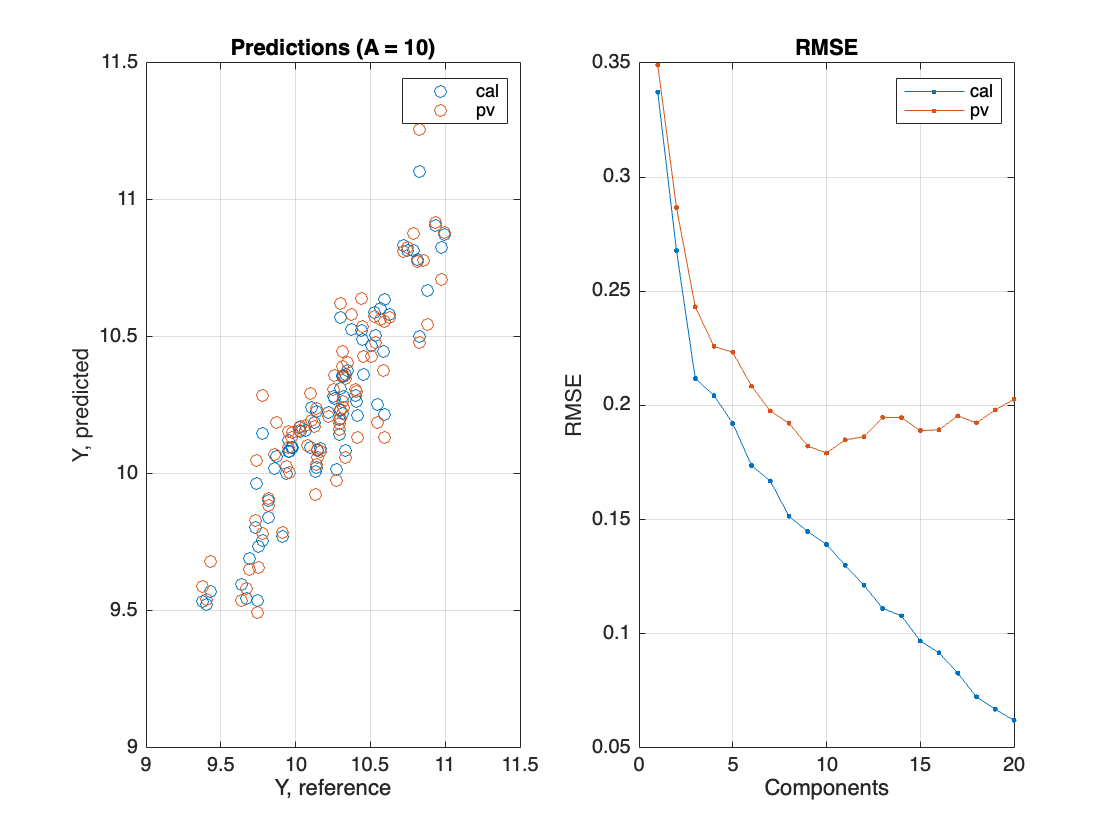

% mean center X-values (both calibration and PV-set)
mX = mean(X);
Xmc = X - mX;
Xpvmc = Xpv - mX;

% mean center Y-values (both calibration and PV-set)
mY = mean(Y);
Ymc = Y - mY;

% compute global PLS model for mean centered X and Y
[P, R, C] = simpls(Xmc, Ymc, A);

% get scores for calibration and PV-sets
T = Xmc * R;
Tpv = Xpvmc * R;

% computed predicted values for each set using different number of LVs.
ypc = zeros(size(X, 1), A);
yppv = zeros(size(X, 1), A);
for a = 1:A
   ypc(:, a) = T(:, 1:a) * C(:, 1:a)';
   yppv(:, a) = Tpv(:, 1:a) * C(:, 1:a)';
end

% uncenter the predicted values
ypc = ypc + mY;
yppv = yppv + mY;

% compute errors of prediction
ec = Y - ypc;
epv = Y - yppv;

% compute RMSE
rmsec = sqrt(sum(ec.^2) / size(X, 1));
rmsepv = sqrt(sum(epv.^2) / size(X, 1));

% show plots with performance
figure

% predicted vs. measured values for A = 10
subplot 121
hold on
scatter(Y, ypc(:, 10))
scatter(Y, yppv(:, 10))
hold off
xlim([9.0, 11.5])
ylim([9.0, 11.5])
xlabel("Y, reference")
ylabel("Y, predicted")
title("Predictions (A = 10)")
grid()
box()
legend(["cal", "pv"])

% RMSE plot
subplot 122
hold on
plot(1:A, rmsec(:), '.-')
plot(1:A, rmsepv(:), '.-')
hold off
xlabel("Components")
ylabel("RMSE")
title("RMSE")
grid()
box()
legend(["cal", "pv"])

As you can notice, the PV-set points at A = 10 as optimal number of LV, while the RMSE for calibration set  does not show any minimum.

Finally, the code below shows how to reproduce the heamap of scaling coefficients, which can be used to test the quality of the PV-set (see the paper for more details).

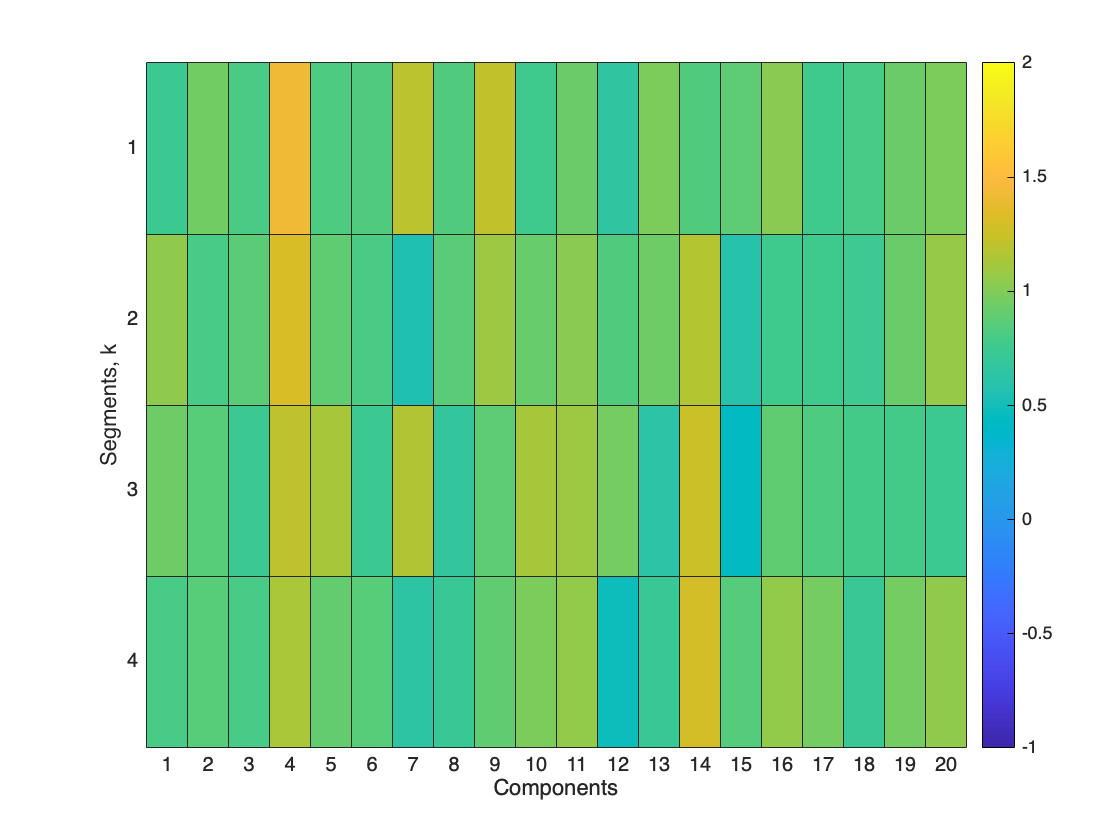

% show plot with scaling coefficients for K = 4
figure

heatmap(D, 'Colormap', parula, 'ColorLimits', [-1, 2])
xlabel("Components")
ylabel("Segments, k")

### Helper functions

Function which computes the two distances for given PCA model, dataset and number of components:

function [h, q] = getdistances(P, lambda, X, A)
   T = X * P(:, 1:A);
   E = X - T * P(:, 1:A)'; 
   q = sum(E.^2, 2);
   h = sum(T.^2 ./ lambda(1:A), 2);
end

Function which shows the distance plot for X and Xpv:

function plotdistances(P, lambda, X, Xpv, A)
   [h, q] = getdistances(P, lambda, X, A);
   [hpv, qpv] = getdistances(P, lambda, Xpv, A);
   
   hold on
   scatter(h / mean(h), q / mean(q), 's')
   scatter(hpv / mean(h), qpv / mean(q), 'x')
   
   hold off
   title(sprintf("Distance plot (A = %d)", A))
   xlabel("Score distance, h/h0")
   ylabel("Orthogonal distance, q/q0")
   grid()
   box()
   legend(["cal", "pv"])
end